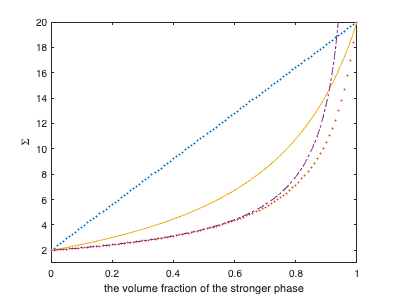

% Handy et al.,1999

% viscosity ratio
  r = 10;
  EI = 1;
% volume fraction of the stronger phase  
  phi=0:0.01:1; 
% Voigt 
  etaV=phi.*r+(1-phi);
  sV = 2*etaV*EI;
% Ruess
  etaR=(phi./r+(1-phi)).^-1;
  sR = 2*etaR*EI;
% Mori-Tanaka  
  etaMT=((2+3.*phi).*r+1-phi)./(2.*(1-phi).*r+1+4.*phi);
  sMT = 2*etaMT*EI;

%   % imposed strain rate
%   E  =[0 1 0;1 0 0;0 0 0];
%   EI = Inva(E);
%   
% % clasts
%   n = 200; 
%   [a,ang]= RandAANG(5,n);
%   q = Qvec(ang); 
%   aa=ones(3,n);
%   etak = r.*rand(n,1)+1;
% 
%   s_MT1 = zeros(1,numel(phi));
%   ei = zeros(n+1,numel(phi));
%   si = ei;
%   for kk=1:numel(phi)
%       % spherical clasts
%       [S_bar,~,Em,Sm,e,s,vis,vis0]=MT_homogenization(E,n,aa,q,r.*ones(n,1),1,ones(n,1),1,phi(kk));
%       s_MT1(kk) = Inva(S_bar);
%       for ii=1:n
%           ei(ii,kk)=Inva(e(:,:,ii));
%           si(ii,kk)=Inva(s(:,:,ii));
%       end
%       ei(end,kk)=Inva(Em);
%       si(end,kk)=Inva(Sm);
%       %vis_MT1(kk)=Inva(S_bar)/EI/2;
%   end

% IWL
   k1 = (1 - phi).^(1/r - 1); %phiw^-x x=1-1/r
   k2 = (1 - phi).^(1/r);   %phiw^(1-x) x=1-1/r
 
   ew = EI.* k1;
   es = EI.* (1 - k2)./phi;
 
   sw = 2*ew*1;
   ss = 2*es*r;

   sIWL = sw.*k2 + ss.*(1 - k2);
  
  % Plot  
%   plot(phi,sV,'.',phi,sR,'.',phi,sMT,'-',phi,s_MT1,':',...
%       phi,sIWL,'-.')
plot(phi,sV,'.',phi,sR,'.',phi,sMT,'-',phi,sIWL,'-.')

  xlim([0 1])
  ylim([1,2*r])

  xlabel('the volume fraction of the stronger phase')
  ylabel('\Sigma')